% Get labels for each image.
load trainingHoGData.mat;


 
rng default
pool = parpool; % Invoke workers

Starting parallel pool (parpool) using the 'local' profile ...
connected to 8 workers.


options = statset('UseParallel',true);
classifier = fitcecoc(hogFeatures, trainingLabels,'Options',options);

testingFolder = 'C:\Users\rickf\Google Drive\Greenstand\SVM\Testing';

imds = imageDatastore(testingFolder,'IncludeSubfolders',true,'LabelSource','foldernames');

imdsAug = augmentedImageDatastore([277,277],imds,'OutputSizeMode','centercrop' );

 

hogTestFeatures = zeros(length(imds.Files),length(hogFeatures));

for i = 1:length(imds.Files)
    try
     dataTable = readByIndex(imdsAug,i);
     img = dataTable{1,1}{1};
     img = SegmentGreenWithOtsu(img);   

    [testFeatures , ~] = extHoGFeatures(img);
    hogTestFeatures(i,:) = testFeatures;
    catch ME
        disp(ME);
    end
end

  MException with properties:

    identifier: 'nnet_cnn:augmentedImageDatastore:invalidCropOutputSize'
       message: 'When 'OutputSizeMode' in augmentedImageDatastore is 'centercrop', requested 'OutputSize' must be smaller than input image size.'
         cause: {0×1 cell}
         stack: [12×1 struct]



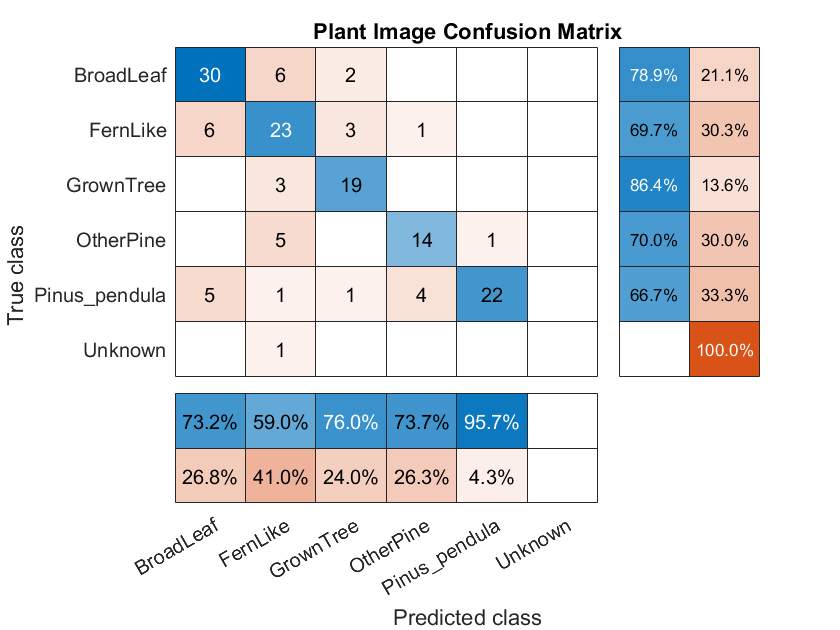

% Make class predictions using the test features.
predictedLabels = predict(classifier, hogTestFeatures);
testLabels = imds.Labels;
% Tabulate the results using a confusion matrix.
[confMat,order] = confusionmat(testLabels, predictedLabels);

figure
cm = confusionchart(confMat,order);

cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'Plant Image Confusion Matrix';